clc, clearvars

# **MRI local wire simulation**

The purpose of wire_function() is to simulate the path of a local wire through the body in the electric field.  

## **Required Inputs**

eField (as a file name):

"simulatedBodyCoilEfield (1).mat"

ans = "simulatedBodyCoilEfield (1).mat"

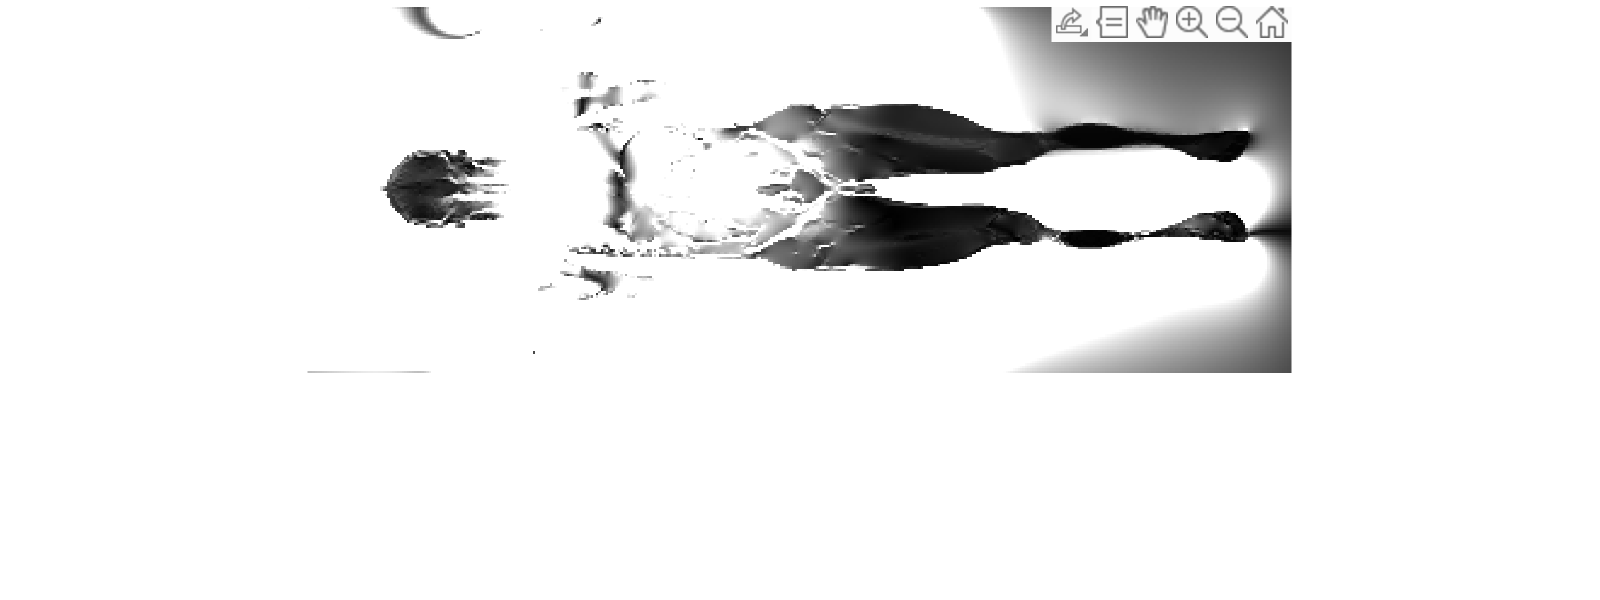

z =   102.0082
  149.8661
  205.9754
  344.5984


x =    72.4932
   85.6954
   66.7172
   10.6079


s = load(ans);
title('Saggital')
imshow(squeeze(abs(s.E(:,75,:,1))))
set(gcf,'Position',[300 300 800 300])

[z, x] = getpts

%set(gca, 'linewidth', 5)

Pick your points for the y direction on the green lines. 

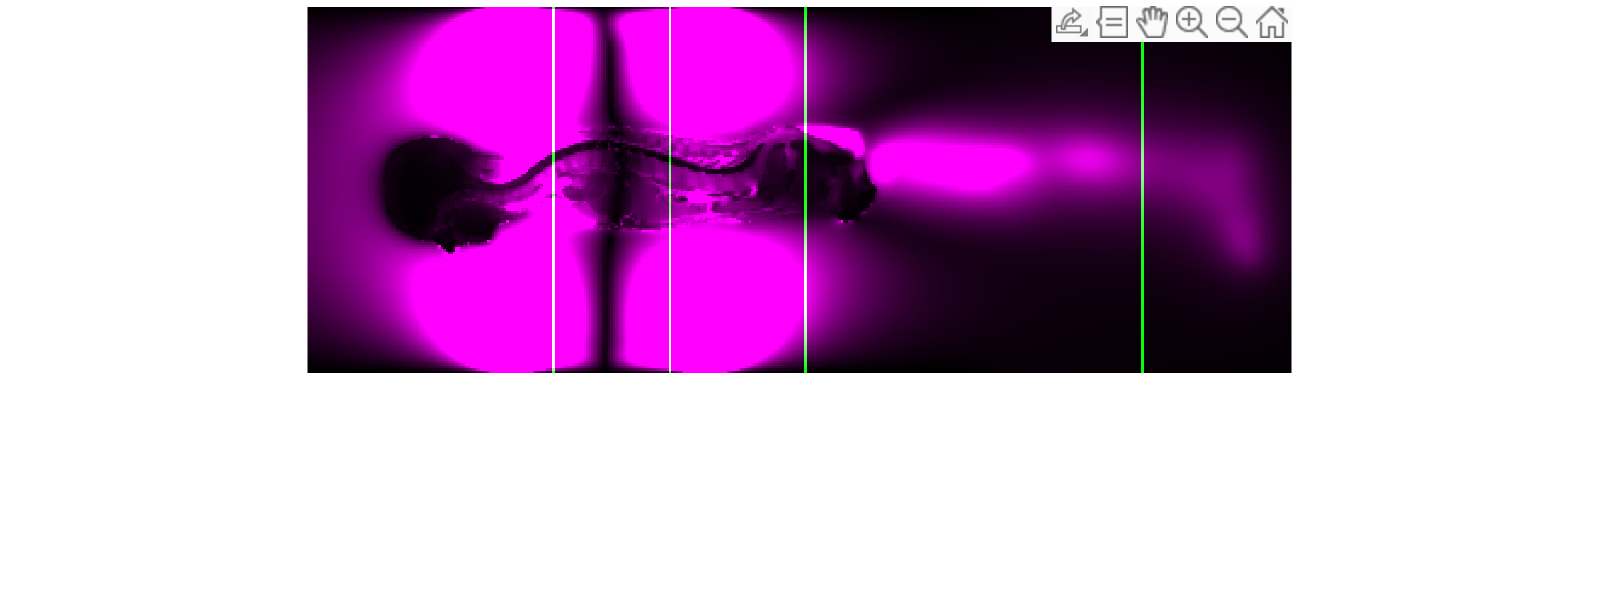


vol = zeros(length(s.axis1)-1, length(s.axis2)-1);
vol(:,round(z)) = 1;

s.E(abs(s.E) > 5) = 5;
imshow(imfuse(vol, squeeze(abs(s.E(75,:,:,1)) ), 'Scaling', 'independent')) 
set(gcf,'Position',[300 300 800 300])
[zc, y] = getpts;

p = [x, y, z];
points = convert_points(p, s, 'version', "v1")

output =      1     1     1
     1     1     1
     1     1     1
     1     1     1


points =    -0.0217   -0.0567   -0.1142
    0.0483    0.0283    0.1258
   -0.0467   -0.1017    0.4058
   -0.3267   -0.2467    1.1008


num_points = size(points, 1);     

Pick the minimum and maximum values for each of your points. 

1) Select a value above and below for the x direction.

2) Select a value to the right and left when choosing z ranges. 

3) Select a value above and below for the y direction. 

Coordinates that you do not specify as changing later on will not be used. **Pick maximum first and minimum second for each point. **

y ranges:

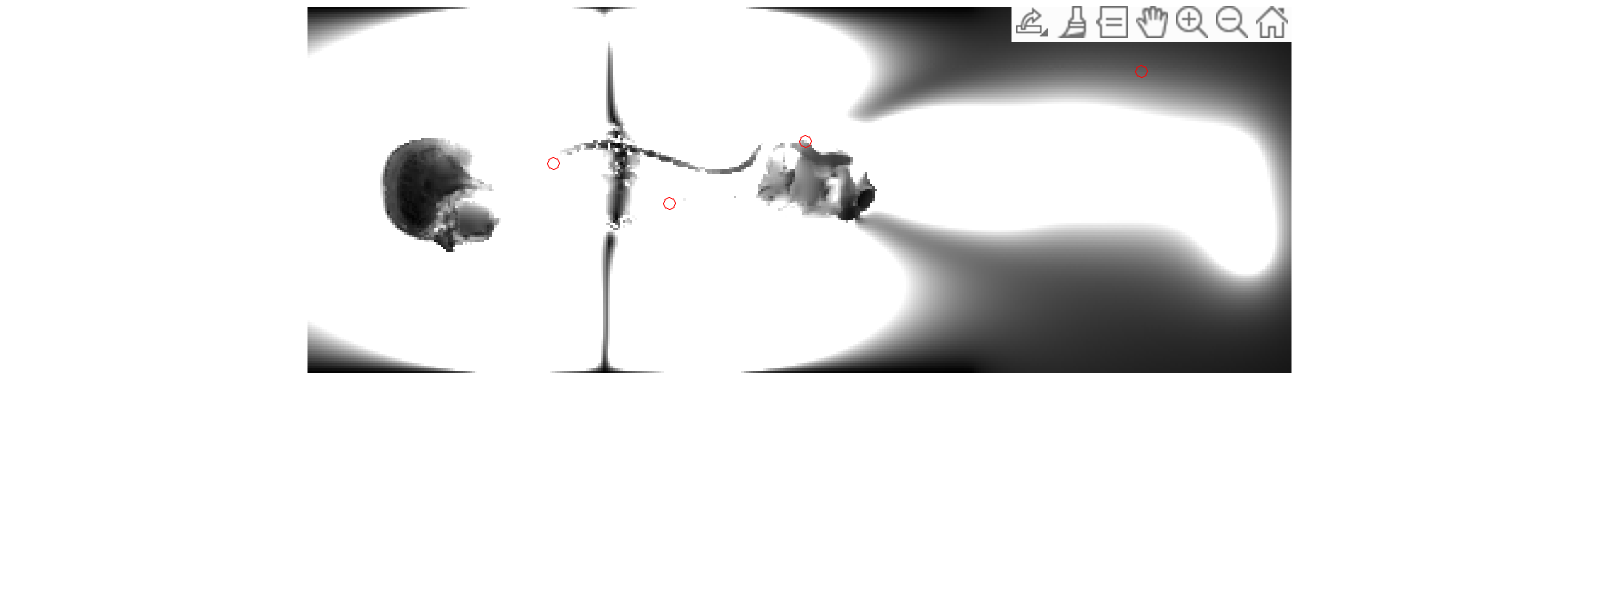

zn =   106.1339
  106.1339
  150.6913
  150.6913
  206.8005
  211.7514
  345.4235
  345.4235


y_ranges =    59.2910
   76.6189
   69.1926
   85.6954
   51.8648
   76.6189
   18.8593
   38.6626


%voll = zeros(length(s.axis1)-1, length(s.axis2)-1);
%voll(round(points()),round(points(:, 1:2))) = 1; %how to only do points?
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[zn, y_ranges] = getpts

y_ranges = reshape(y_ranges, 2, num_points)' %check if order is correct

y_ranges =    59.2910   76.6189
   69.1926   85.6954
   51.8648   76.6189
   18.8593   38.6626


y_ranges = convert_points(y_ranges, s, 'version', "v2", 'yd', "T")

y_ranges =    -0.0867    0.0033
   -0.0367    0.0483
   -0.1217    0.0033
   -0.2867   -0.1867


z ranges:

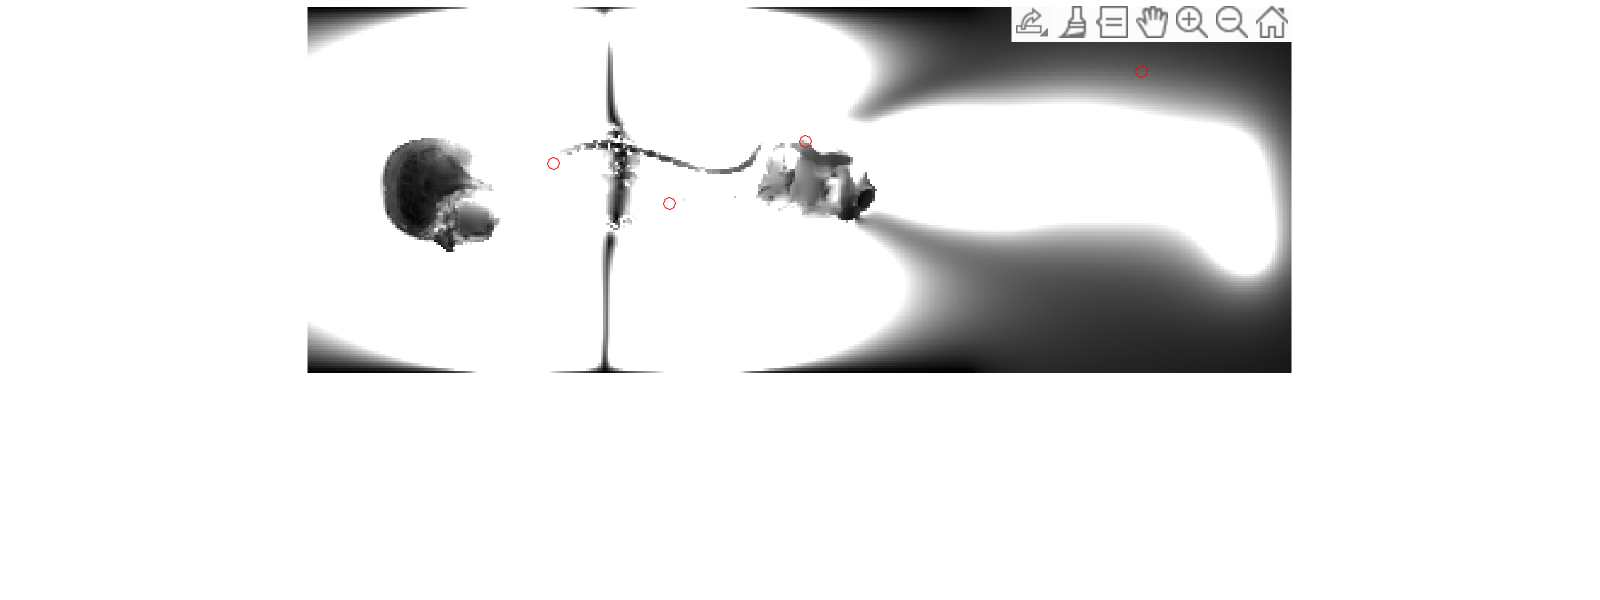

z_ranges =    85.5055
  116.8607
  137.4891
  171.3197
  194.4235
  232.3798
  334.6967
  363.5765


yn =    67.5423
   67.5423
   79.9194
   79.9194
   55.1653
   55.1653
   27.1107
   27.1107


%same plot
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[z_ranges, yn] = getpts

z_ranges = reshape(z_ranges, 2, num_points)'%convert points

z_ranges =    85.5055  116.8607
  137.4891  171.3197
  194.4235  232.3798
  334.6967  363.5765


z_ranges = convert_points(z_ranges, s, 'version', "v2", 'zd', "T")

z_ranges =    -0.1942   -0.0392
    0.0608    0.2308
    0.3458    0.5358
    1.0508    1.1958


x ranges:

imshow(squeeze(abs(s.E(:,75,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, x, 'ro');
hold off
[zn, x_ranges] = getpts

zn =   102.0082
  102.8333
  139.1393
  149.8661
  207.6257
  207.6257
  321.4945
  321.4945


x_ranges =    60.1161
   88.1708
   71.6680
  103.8484
   51.0396
   87.3456
   18.8593
   32.0615


x_ranges = reshape(x_ranges, 2, num_points)'

x_ranges =    60.1161   88.1708
   71.6680  103.8484
   51.0396   87.3456
   18.8593   32.0615


%x_ranges = reshape(x_ranges, 2, [])'
x_ranges = convert_points(x_ranges, s, 'version', "v2", 'xd', "T")

x_ranges =    -0.0817    0.0583
   -0.0217    0.1383
   -0.1267    0.0533
   -0.2867   -0.2217


ranges = [x_ranges y_ranges z_ranges];

which points will be changing (give a list of their indices): 

[1 2 3]

ans =      1     2     3


check of all of the points that are changing:

changing = ans;

## **Optional Inputs**

Drag to choose how long you want your wire to be. Your points will be adjusted to this length. Units are in meters. 

1

ans = 1

nom_length = ans;

Do you want a plot of the wire to be displayed?

"Yes" 

ans = "Yes"

if ans == "Yes"
    show_plot = true;
else
    show_plot = false;
end

Do you want a histogram of the lengths of the trajectories for the wire (modified and unmodified) to be displayed?

"Yes"

ans = "Yes"

if ans == 'Yes'
    show_graph = true;
else
    show_graph = false;
end

What is the indice of the point on the wire that intersects with the body?

3

ans = 3

intersecting = ans;

Drag to pick the number of steps between ranges. For example, if there is a range [-1 2] and num_steps is 3, the function will use 3 values in between -1  and 2. Default value: 5. num_steps^3 is the number of trajectories that will be calculated. 

5

ans = 5

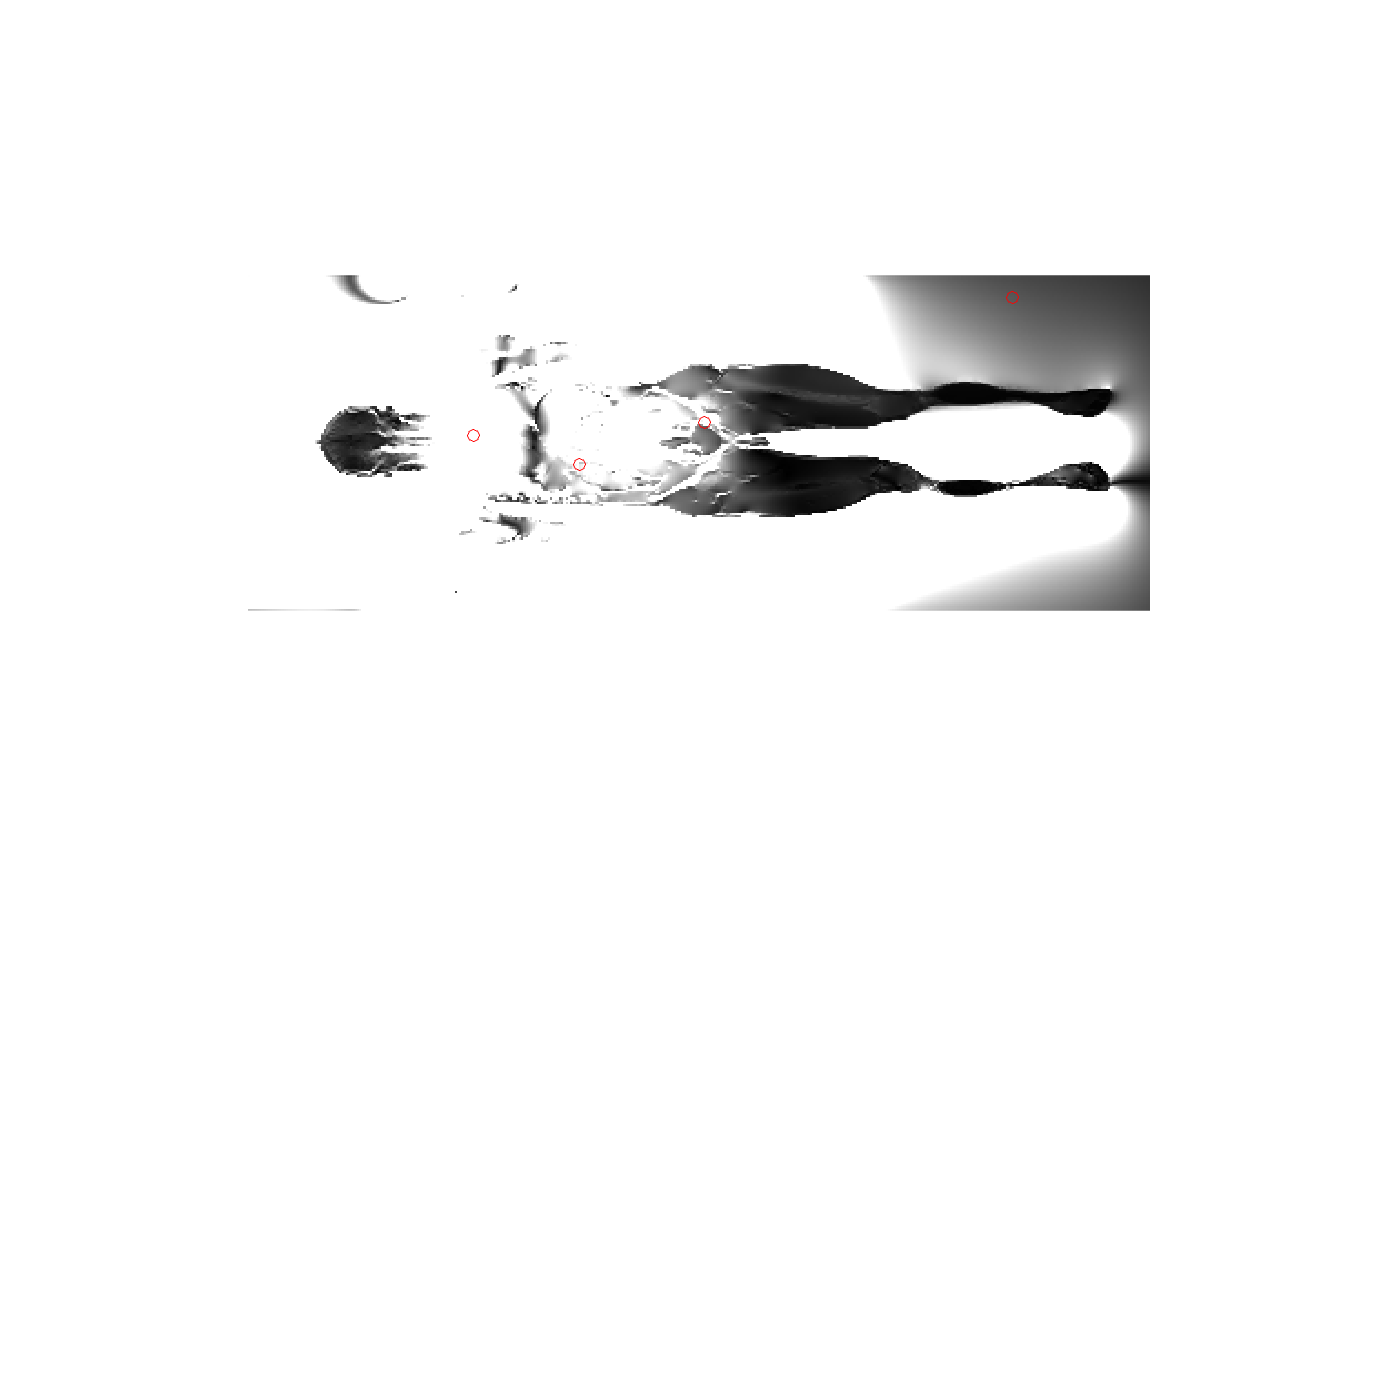

num_steps = ans;
set(gcf,'Position',[300 300 700 700]) %weird transition

show_electric = logical
   1


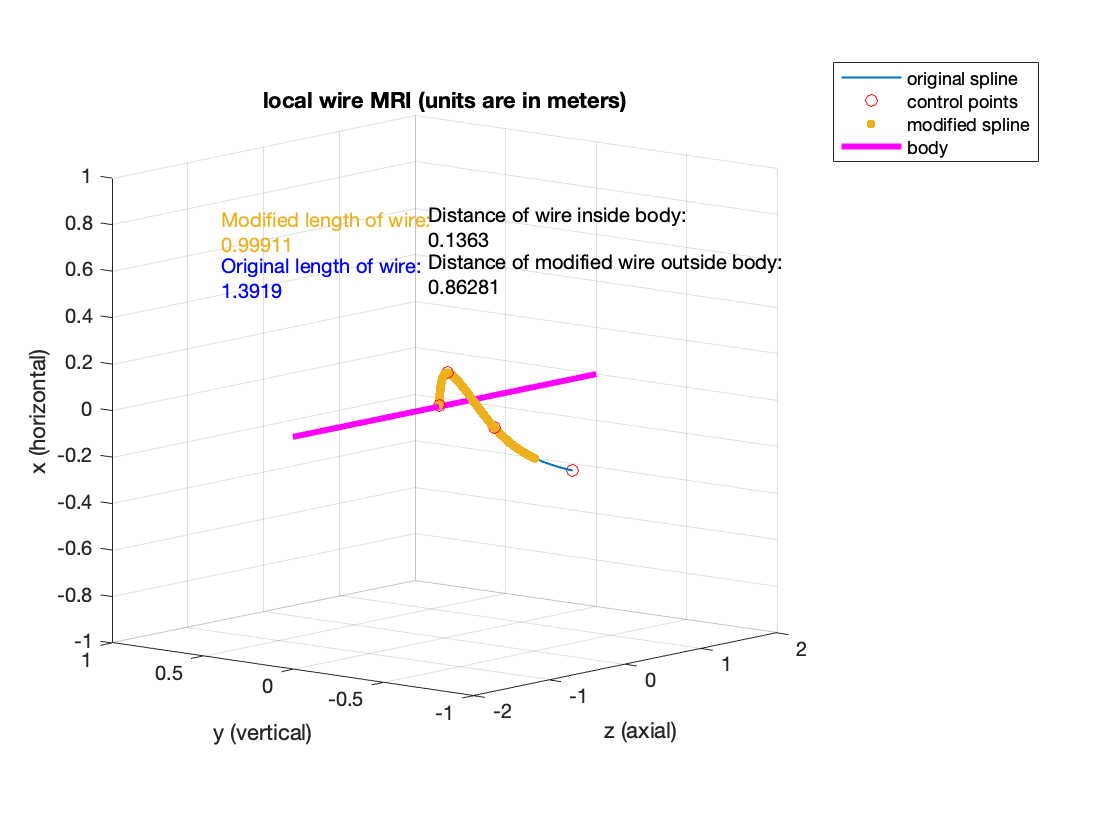

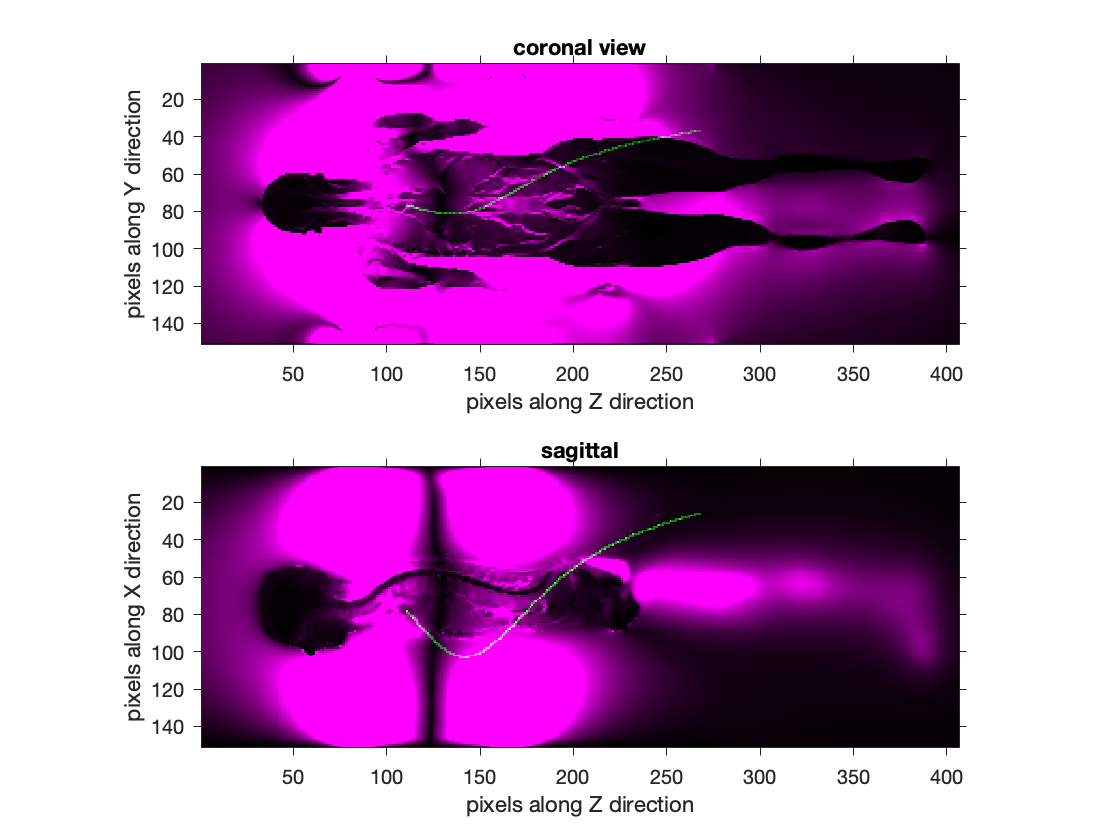

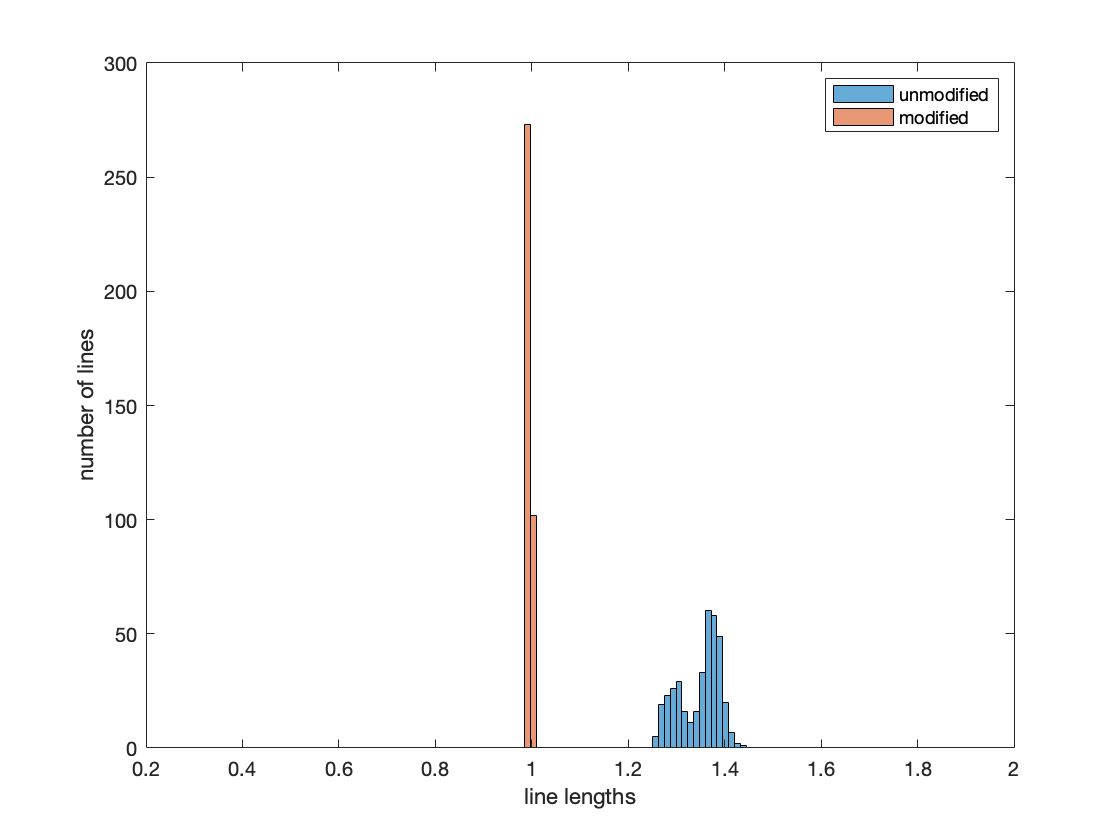

[output, wire_lengths, output3] = wire_function_v8(...
    points',...
    ranges,...
    changing,...
    s,...
    'nom_length', nom_length,...
    'show_plot', show_plot,...
    'show_graph', show_graph,...
    'intersecting_index', intersecting,...
    'num_steps', num_steps,... 
    'give_warnings', false, ... 
    'direction', "Right");